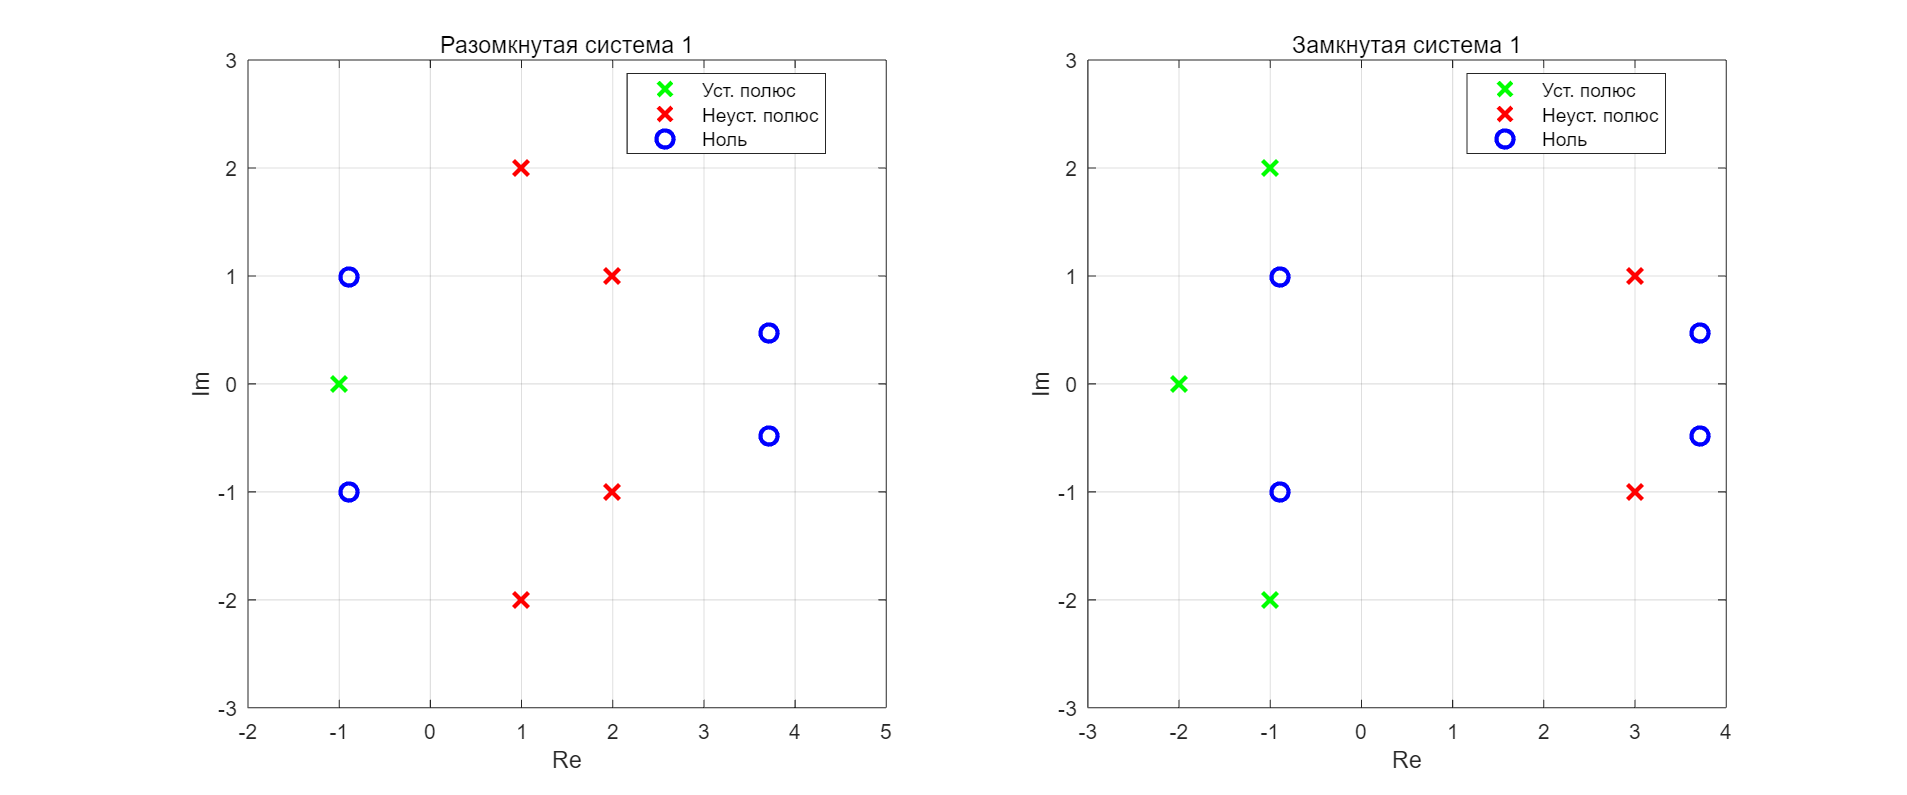

% Система 1
p1 = [-1, 2+1i, 2-1i, 1+2i, 1-2i];
z1 = roots([3, -17, 8, 35, 75]);
K1 = 3;
Q_closed_coeffs1 = [1, -2, -5, -4, 30, 100];
num1 = K1 * poly(z1);
den1 = poly(p1);
open_sys1 = tf(num1, den1);
R_s1 = Q_closed_coeffs1 - den1;
closed_sys1 = tf(R_s1, den1 + R_s1); 
p_closed1 = roots(den1 + R_s1);
z_closed1 = roots(R_s1);

figure('Position', [100 100 1200 500]);
set(gcf, 'Color', 'w');

subplot(1,2,1);
hold on;
grid on;
xlabel('Re');
ylabel('Im');
title('Разомкнутая система 1', 'FontWeight', 'normal');

for i = 1:length(p1)
    if real(p1(i)) < 0
        plot(real(p1(i)), imag(p1(i)), 'xg', 'MarkerSize', 10, 'LineWidth', 2);
    else
        plot(real(p1(i)), imag(p1(i)), 'xr', 'MarkerSize', 10, 'LineWidth', 2);
    end
end
for i = 1:length(z1)
    plot(real(z1(i)), imag(z1(i)), 'bo', 'MarkerSize', 8, 'LineWidth', 2);
end
xlim([-2 5]);
ylim([-3 3]);
box on;
h1 = plot(NaN, NaN, 'xg', 'MarkerSize', 10, 'LineWidth', 2);
h2 = plot(NaN, NaN, 'xr', 'MarkerSize', 10, 'LineWidth', 2);
h3 = plot(NaN, NaN, 'bo', 'MarkerSize', 8, 'LineWidth', 2);
legend([h1, h2, h3], {'Уст. полюс', 'Неуст. полюс', 'Ноль'}, 'Location', 'best');

subplot(1,2,2);
hold on;
grid on;
xlabel('Re');
ylabel('Im');
title('Замкнутая система 1', 'FontWeight', 'normal');
p_closed1 = pole(closed_sys1);
z_closed1 = zero(closed_sys1);
for i = 1:length(p_closed1)
    if real(p_closed1(i)) < 0
        plot(real(p_closed1(i)), imag(p_closed1(i)), 'xg', 'MarkerSize', 10, 'LineWidth', 2);
    else
        plot(real(p_closed1(i)), imag(p_closed1(i)), 'xr', 'MarkerSize', 10, 'LineWidth', 2);
    end
end
for i = 1:length(z_closed1)
    plot(real(z_closed1(i)), imag(z_closed1(i)), 'bo', 'MarkerSize', 8, 'LineWidth', 2);
end
xlim([-3 4]);
ylim([-3 3]);
box on;
h1 = plot(NaN, NaN, 'xg', 'MarkerSize', 10, 'LineWidth', 2);
h2 = plot(NaN, NaN, 'xr', 'MarkerSize', 10, 'LineWidth', 2);
h3 = plot(NaN, NaN, 'bo', 'MarkerSize', 8, 'LineWidth', 2);
legend([h1, h2, h3], {'Уст. полюс', 'Неуст. полюс', 'Ноль'}, 'Location', 'best');

exportgraphics(gcf, "images/pz_combined1.png", Resolution=200);

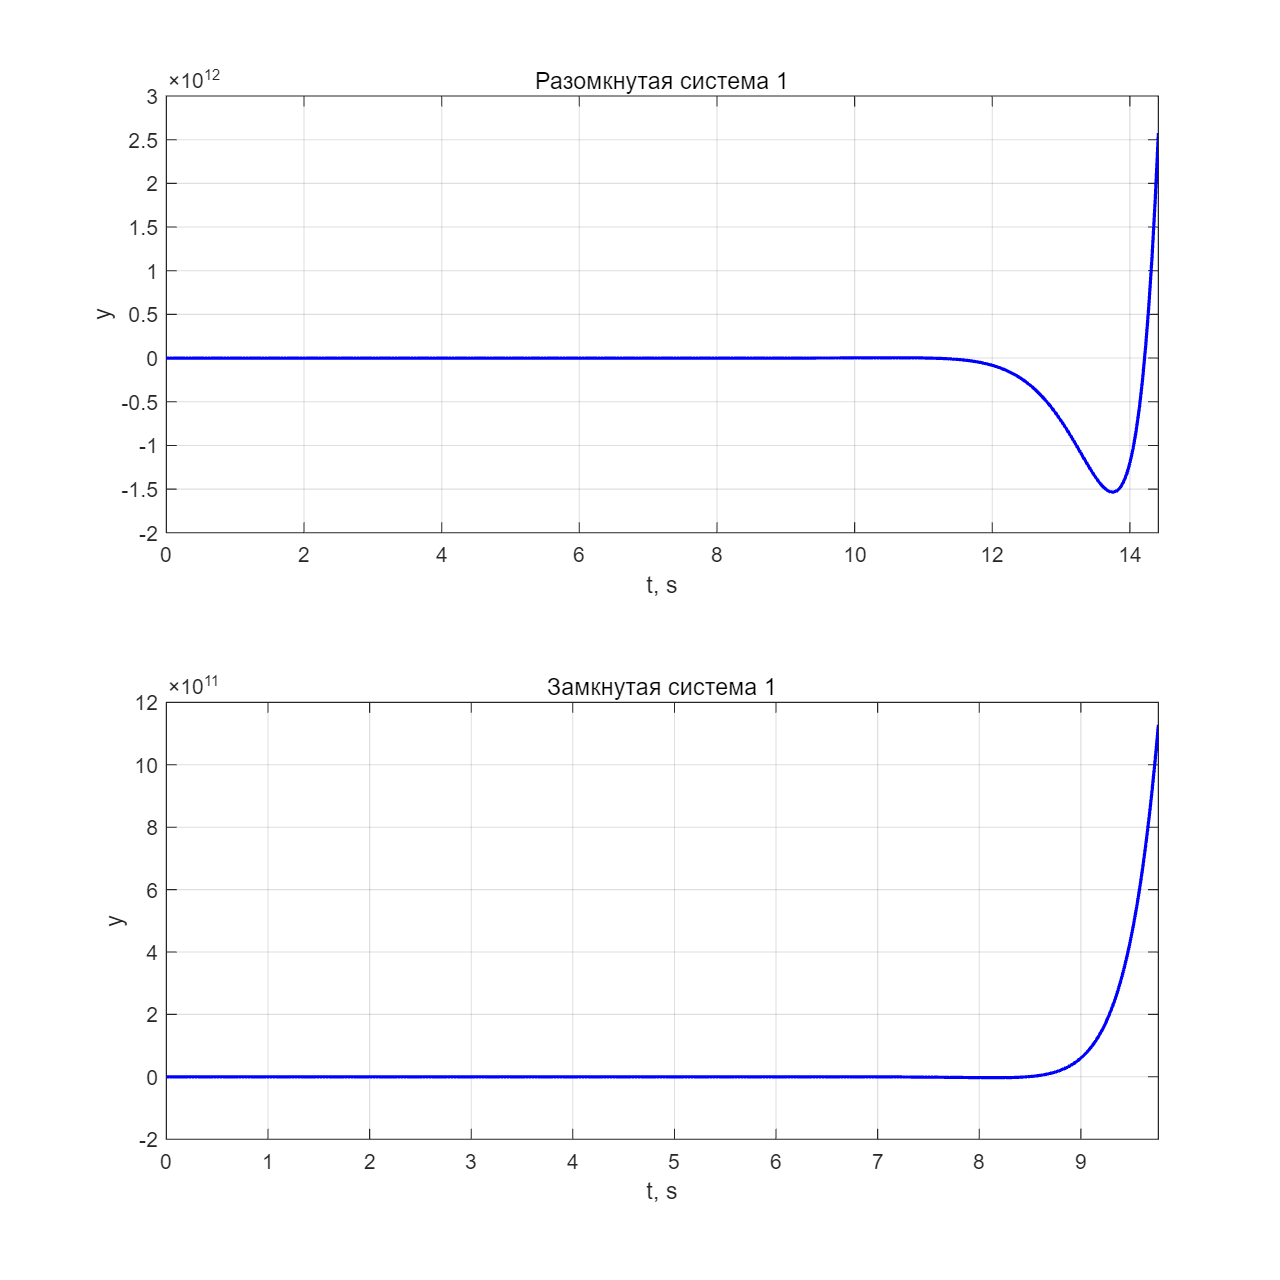


figure('Position', [100 100 800 800]);
set(gcf, 'Color', 'w');

subplot(2,1,1);
[y_open1, t1] = step(open_sys1);
plot(t1, y_open1, 'b', 'LineWidth', 1.5);
xlabel('t, s');
ylabel('y');
grid on;
title('Разомкнутая система 1', 'FontWeight', 'normal');
xlim([0 max(t1)]);

subplot(2,1,2);
[y_closed1, t_closed1] = step(closed_sys1);
plot(t_closed1, y_closed1, 'b', 'LineWidth', 1.5);
xlabel('t, s');
ylabel('y');
grid on;
title('Замкнутая система 1', 'FontWeight', 'normal');
xlim([0 max(t_closed1)]);

exportgraphics(gcf, "images/step_combined1.png", Resolution=200);

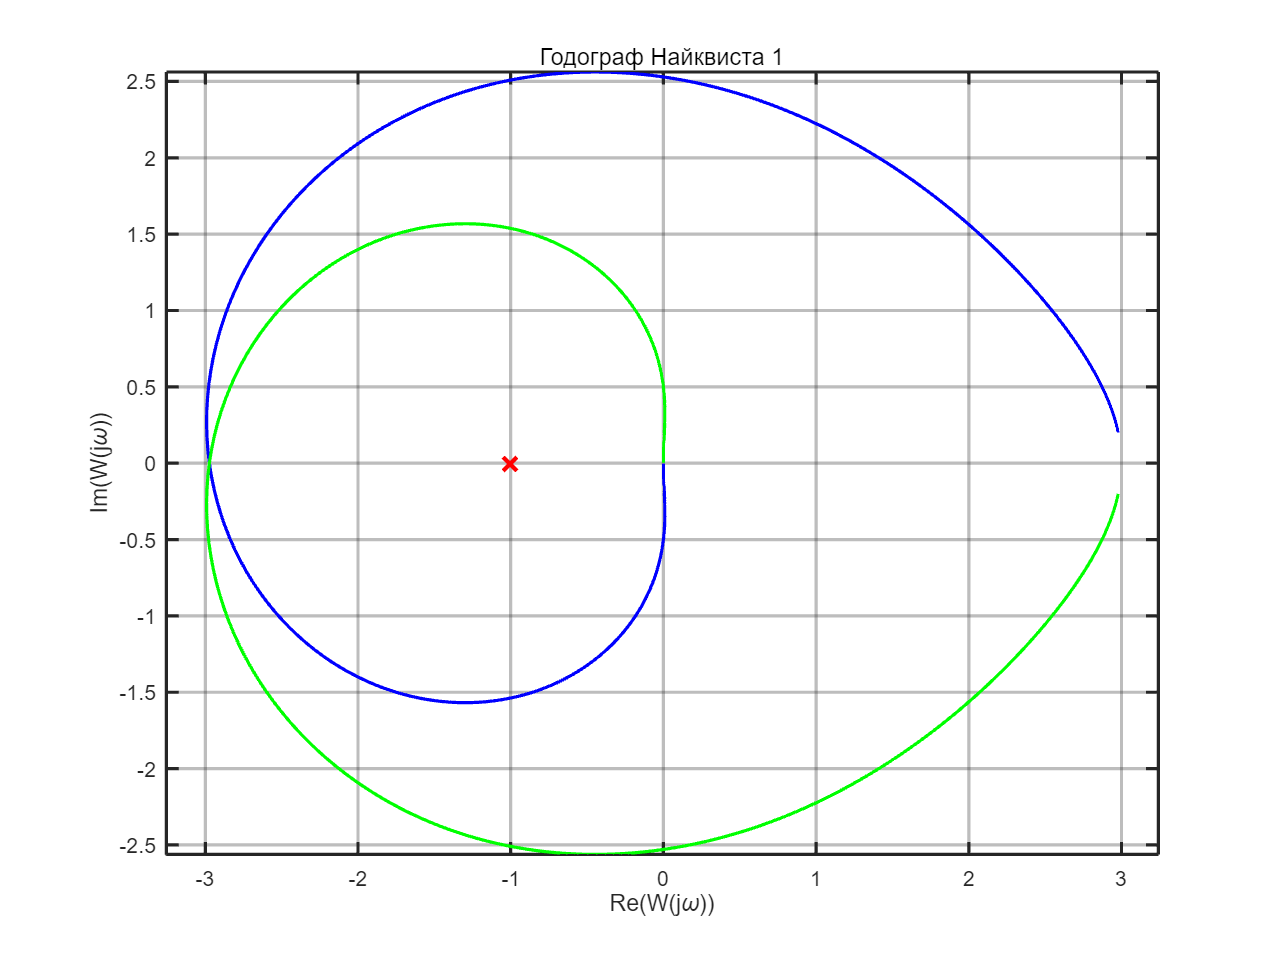


figure('Position', [100 100 800 600]);
set(gcf, 'Color', 'w');

w = logspace(-1, 3, 1000);
[re1, im1] = nyquist(open_sys1, w);
re1 = squeeze(re1);
im1 = squeeze(im1);

plot(re1, im1, 'b', 'LineWidth', 1.5);
hold on;
plot(re1, -im1, 'g', 'LineWidth', 1.5, 'LineStyle', '-');
plot(-1, 0, 'xr', 'MarkerSize', 9, 'LineWidth', 2);
xlabel('Re(W(j\omega))');
ylabel('Im(W(j\omega))');
grid on;
title('Годограф Найквиста 1', 'FontWeight', 'normal');
axis equal;
box on;
ax = gca;
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.GridLineStyle = '-';
ax.GridAlpha = 0.3;
ax.LineWidth = 1.5;

exportgraphics(gcf, "images/nyquist1.png", Resolution=200);

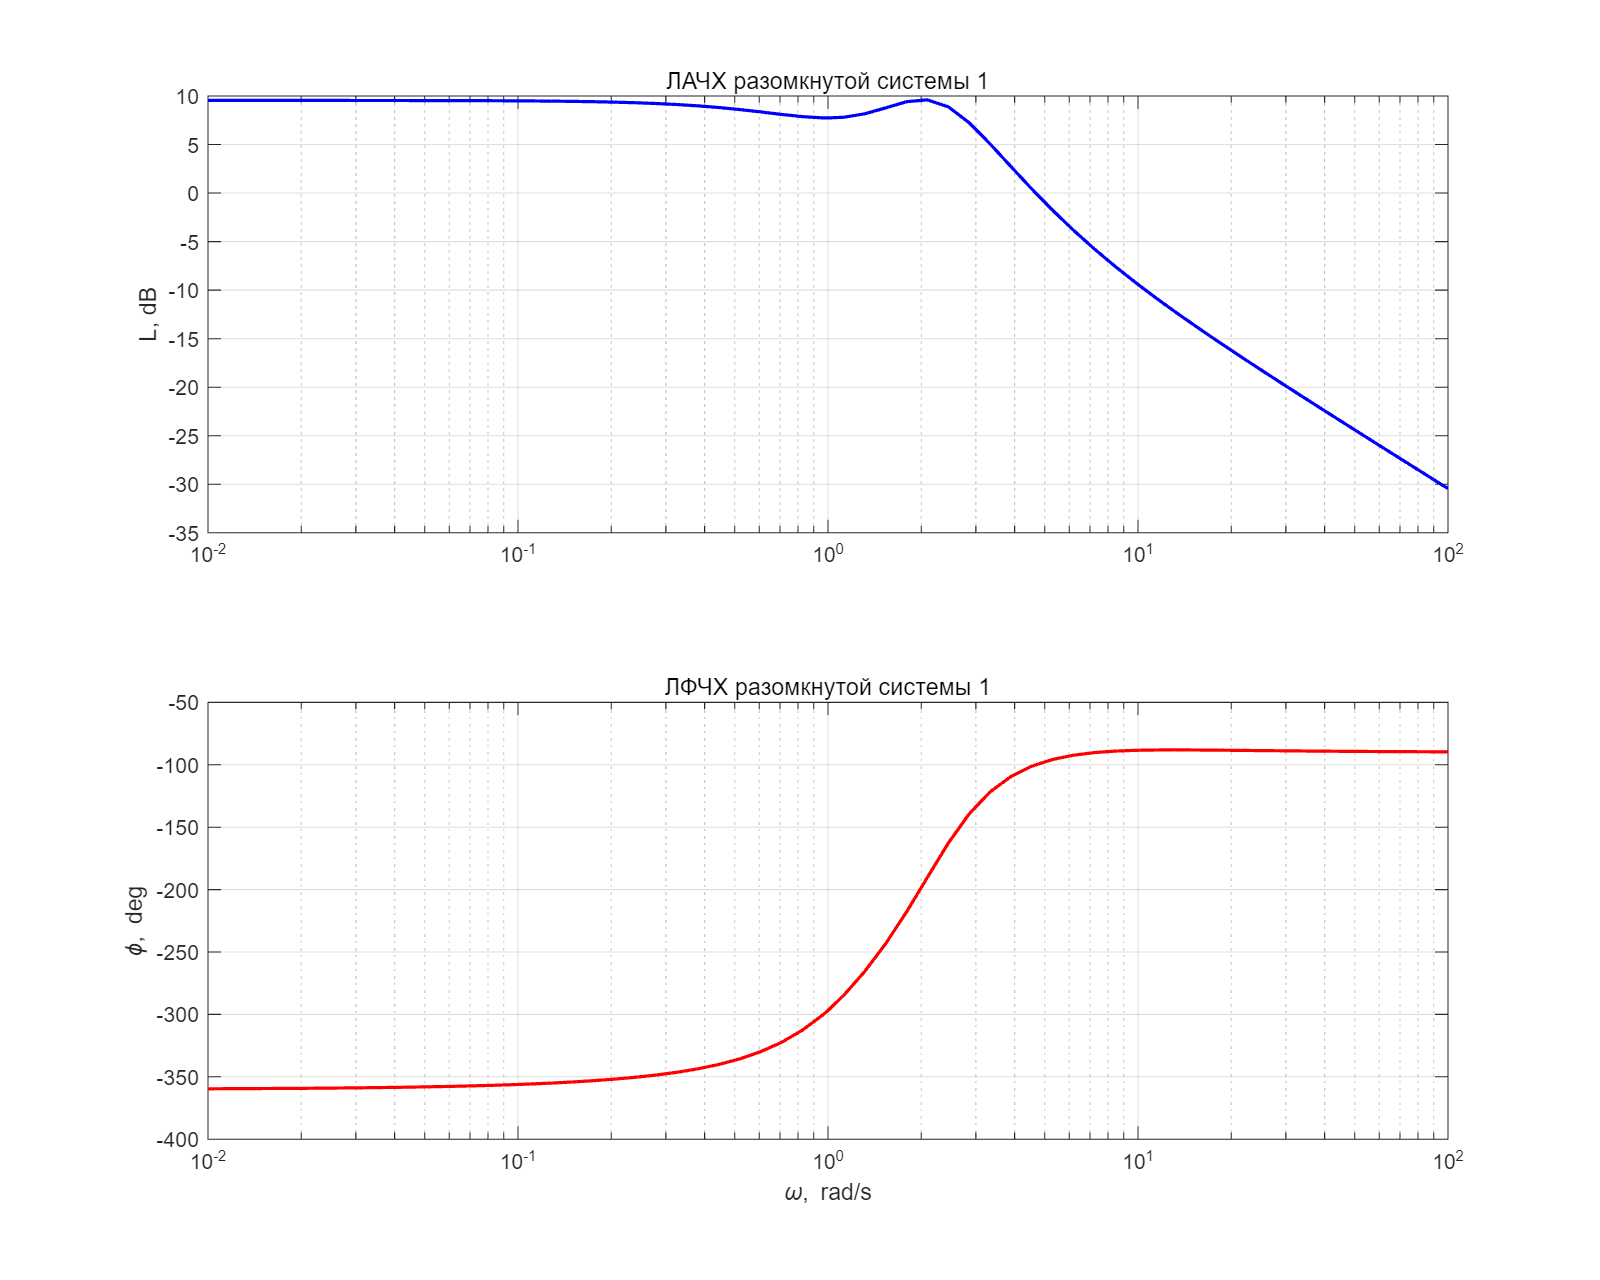


figure('Position', [100 100 1000 800]);
set(gcf, 'Color', 'w');

[mag1, phase1, w1] = bode(open_sys1);
mag1 = squeeze(mag1);
phase1 = squeeze(phase1);

subplot(2,1,1);
semilogx(w1, 20*log10(mag1), 'b', 'LineWidth', 1.5);
grid on;
ylabel('L, dB');
title('ЛАЧХ разомкнутой системы 1', 'FontWeight', 'normal');

subplot(2,1,2);
semilogx(w1, phase1, 'r', 'LineWidth', 1.5);
grid on;
xlabel('\omega, rad/s');
ylabel('\phi, deg');
title('ЛФЧХ разомкнутой системы 1', 'FontWeight', 'normal');

exportgraphics(gcf, "images/bode1.png", Resolution=200);

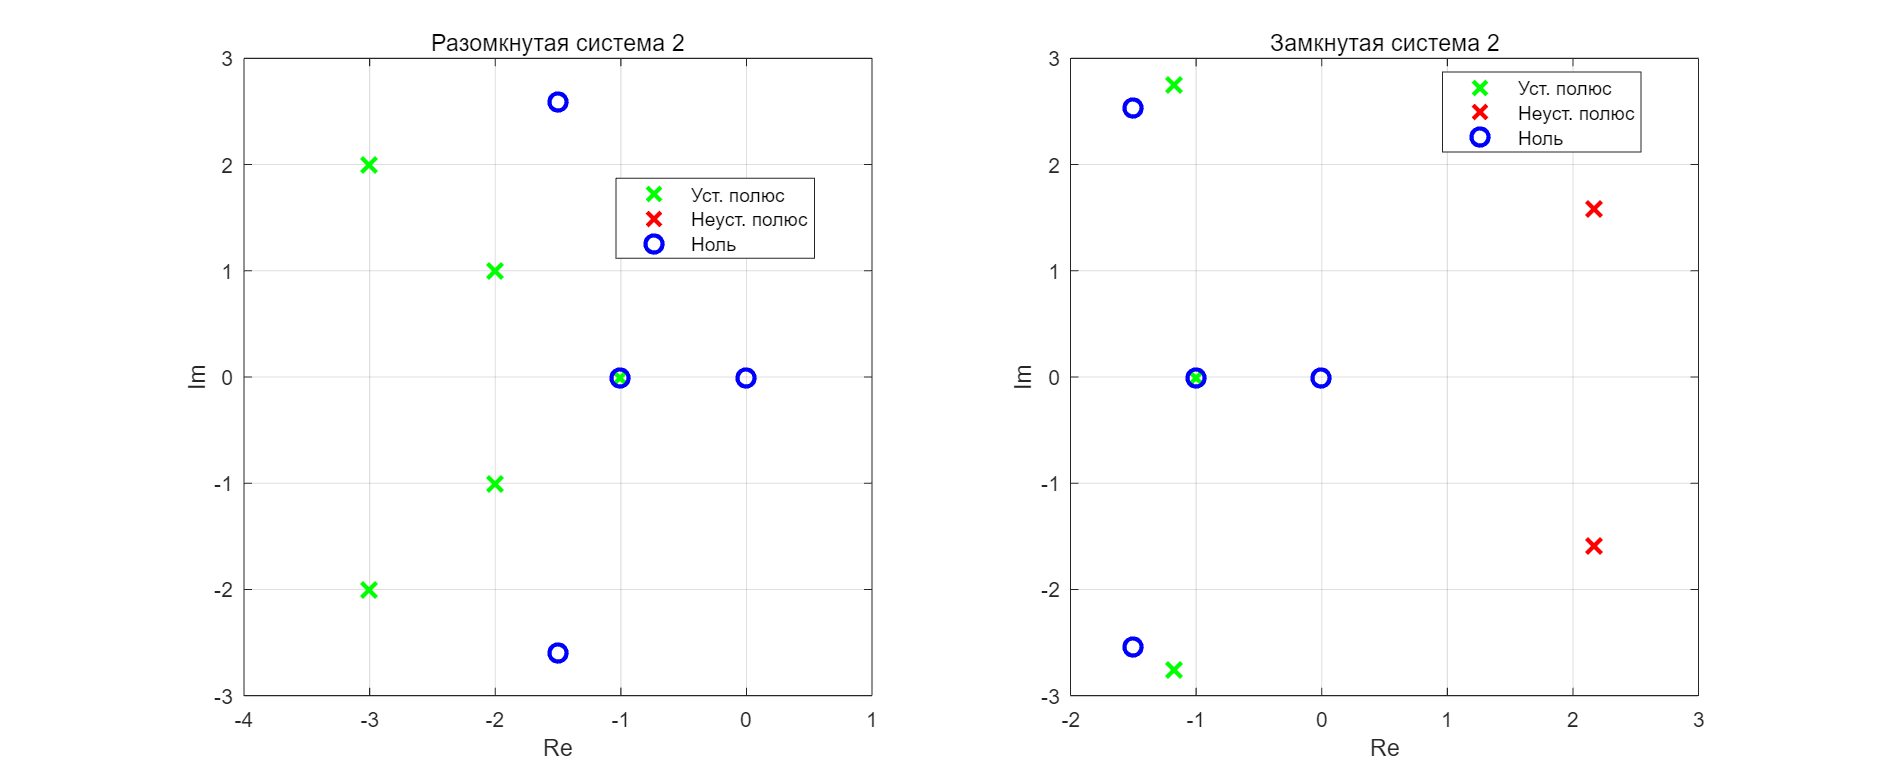

% Система 2
p2 = [-1, -2+1i, -2-1i, -3+2i, -3-2i];
z2 = roots([-12, -48, -144, -108, 0]);
K2 = -12;
Q_closed_coeffs2 = [1, -1, 4, -16, 43, 65];
num2 = K2 * poly(z2);
den2 = poly(p2);
open_sys2 = tf(num2, den2);
R_s2 = Q_closed_coeffs2 - den2;
closed_sys2 = tf(R_s2, den2 + R_s2); 
p_closed2 = roots(den2 + R_s2);
z_closed2 = roots(R_s2);


figure('Position', [100 100 1200 500]);
set(gcf, 'Color', 'w');

subplot(1,2,1);
hold on;
grid on;
xlabel('Re');
ylabel('Im');
title('Разомкнутая система 2', 'FontWeight', 'normal');

for i = 1:length(p2)
    if real(p2(i)) < 0
        plot(real(p2(i)), imag(p2(i)), 'xg', 'MarkerSize', 10, 'LineWidth', 2);
    else
        plot(real(p2(i)), imag(p2(i)), 'xr', 'MarkerSize', 10, 'LineWidth', 2);
    end
end
for i = 1:length(z2)
    plot(real(z2(i)), imag(z2(i)), 'bo', 'MarkerSize', 8, 'LineWidth', 2);
end
xlim([-4 1]);
ylim([-3 3]);
box on;
h1 = plot(NaN, NaN, 'xg', 'MarkerSize', 10, 'LineWidth', 2);
h2 = plot(NaN, NaN, 'xr', 'MarkerSize', 10, 'LineWidth', 2);
h3 = plot(NaN, NaN, 'bo', 'MarkerSize', 8, 'LineWidth', 2);
legend([h1, h2, h3], {'Уст. полюс', 'Неуст. полюс', 'Ноль'}, 'Location', 'best');

subplot(1,2,2);
hold on;
grid on;
xlabel('Re');
ylabel('Im');
title('Замкнутая система 2', 'FontWeight', 'normal');

for i = 1:length(p_closed2)
    if real(p_closed2(i)) < 0
        plot(real(p_closed2(i)), imag(p_closed2(i)), 'xg', 'MarkerSize', 10, 'LineWidth', 2);
    else
        plot(real(p_closed2(i)), imag(p_closed2(i)), 'xr', 'MarkerSize', 10, 'LineWidth', 2);
    end
end
for i = 1:length(z_closed2)
    plot(real(z_closed2(i)), imag(z_closed2(i)), 'bo', 'MarkerSize', 8, 'LineWidth', 2);
end
xlim([-2 3]);
ylim([-3 3]);
box on;
h1 = plot(NaN, NaN, 'xg', 'MarkerSize', 10, 'LineWidth', 2);
h2 = plot(NaN, NaN, 'xr', 'MarkerSize', 10, 'LineWidth', 2);
h3 = plot(NaN, NaN, 'bo', 'MarkerSize', 8, 'LineWidth', 2);
legend([h1, h2, h3], {'Уст. полюс', 'Неуст. полюс', 'Ноль'}, 'Location', 'best');

exportgraphics(gcf, "images/pz_combined2.png", Resolution=200);

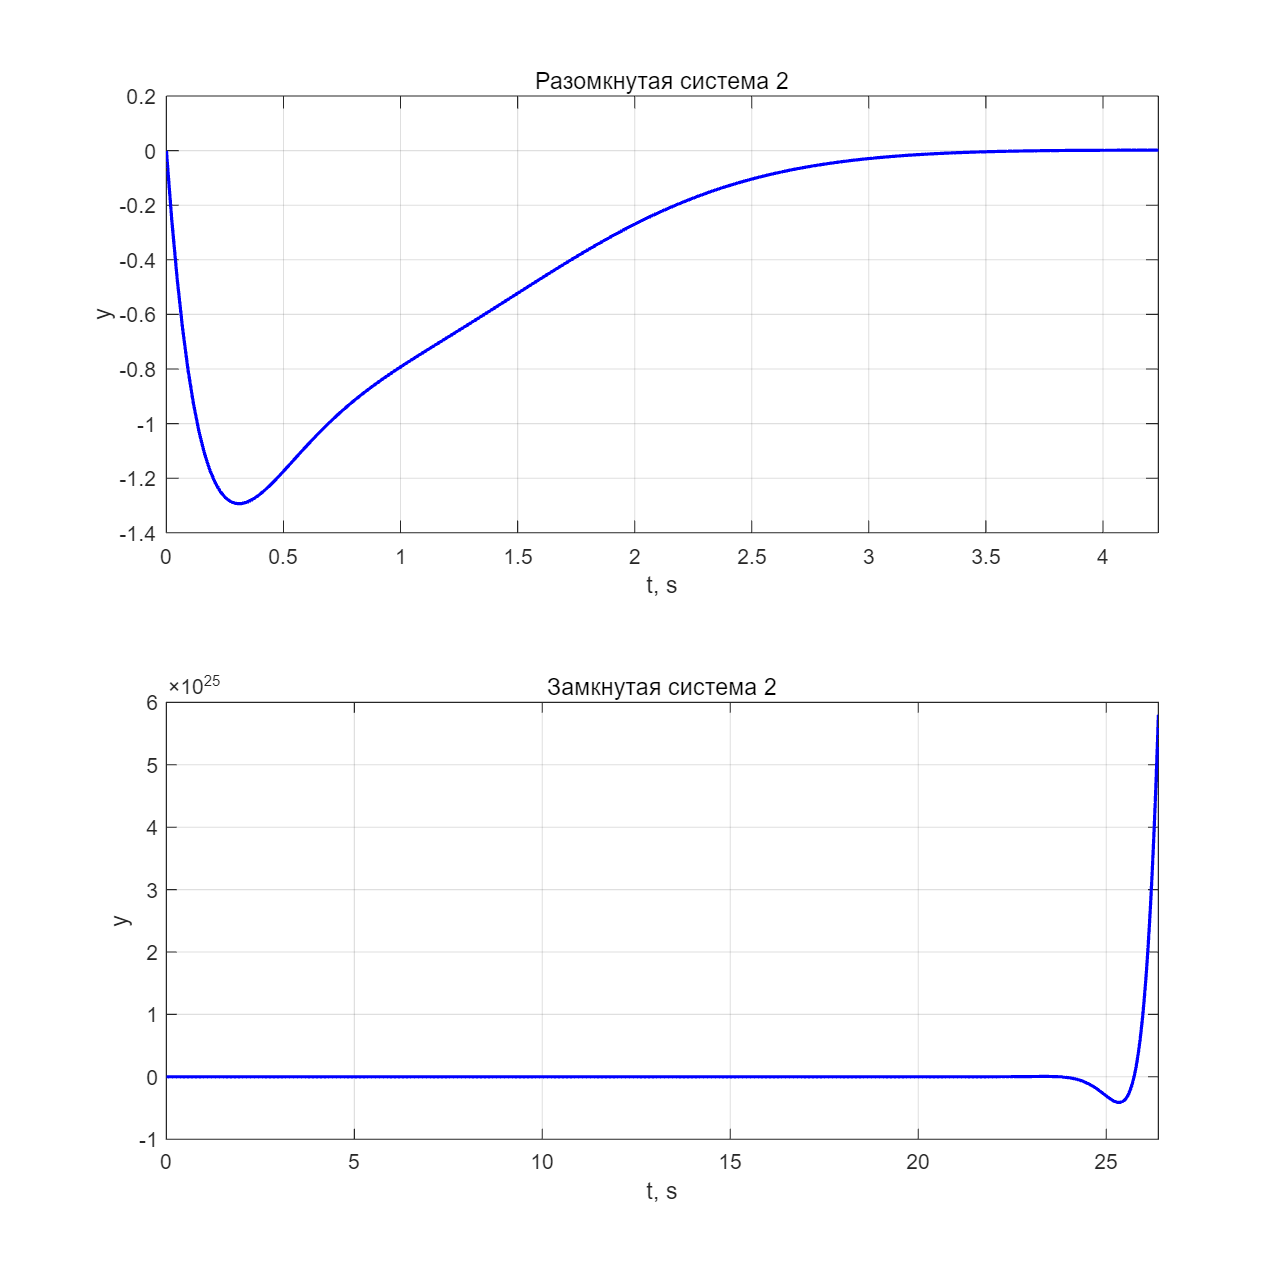


figure('Position', [100 100 800 800]);
set(gcf, 'Color', 'w');

subplot(2,1,1);
[y_open2, t2] = step(open_sys2);
plot(t2, y_open2, 'b', 'LineWidth', 1.5);
xlabel('t, s');
ylabel('y');
grid on;
title('Разомкнутая система 2', 'FontWeight', 'normal');
xlim([0 max(t2)]);

subplot(2,1,2);
[y_closed2, t_closed2] = step(closed_sys2);
plot(t_closed2, y_closed2, 'b', 'LineWidth', 1.5);
xlabel('t, s');
ylabel('y');
grid on;
title('Замкнутая система 2', 'FontWeight', 'normal');
xlim([0 max(t_closed2)]);

exportgraphics(gcf, "images/step_combined2.png", Resolution=200);

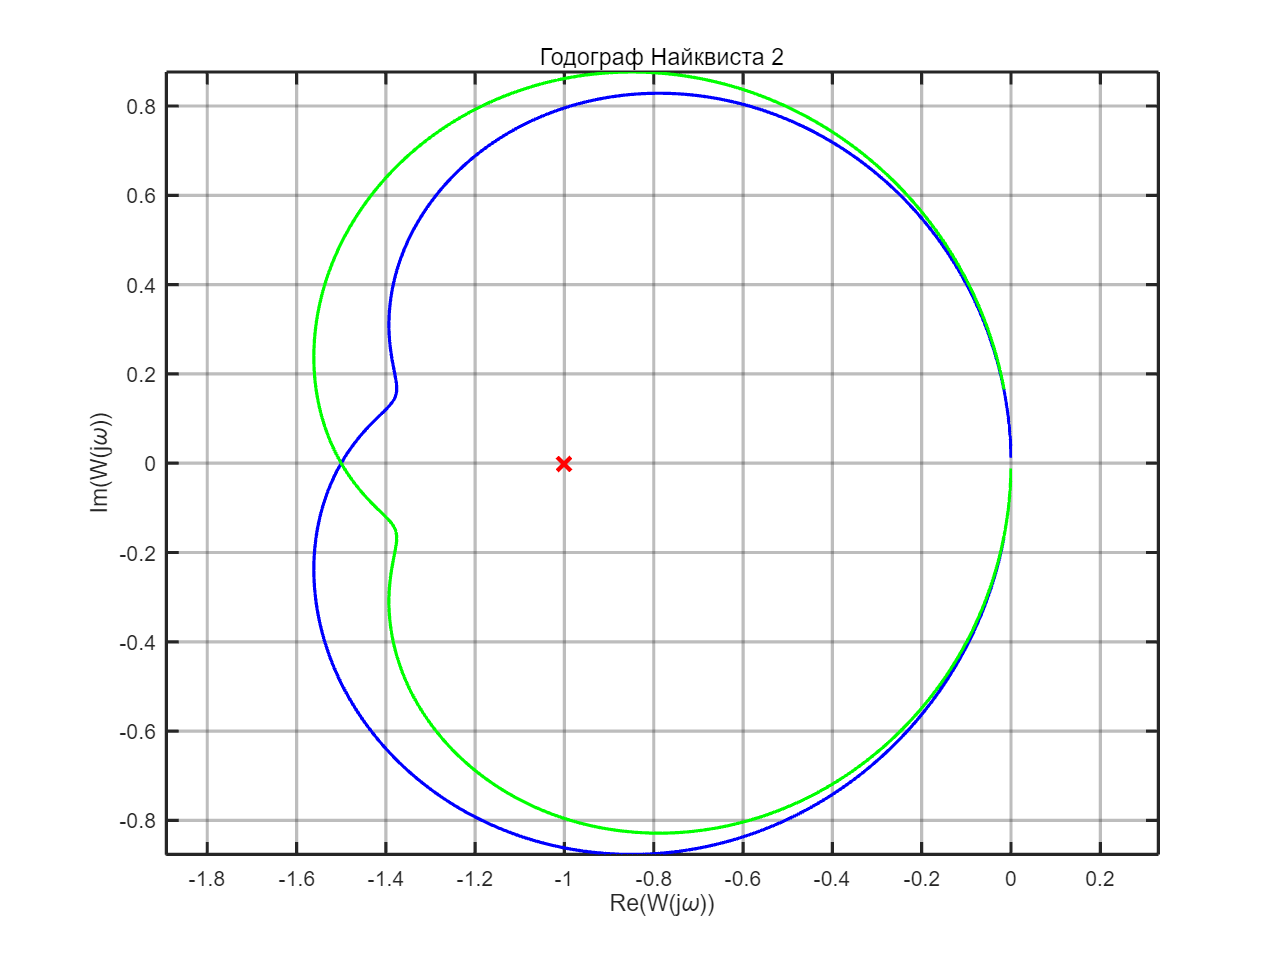


figure('Position', [100 100 800 600]);
set(gcf, 'Color', 'w');

[re2, im2] = nyquist(open_sys2, w);
re2 = squeeze(re2);
im2 = squeeze(im2);

plot(re2, im2, 'b', 'LineWidth', 1.5);
hold on;
plot(re2, -im2, 'g', 'LineWidth', 1.5, 'LineStyle', '-');
plot(-1, 0, 'xr', 'MarkerSize', 9, 'LineWidth', 2);
xlabel('Re(W(j\omega))');
ylabel('Im(W(j\omega))');
grid on;
title('Годограф Найквиста 2', 'FontWeight', 'normal');
axis equal;
box on;
ax = gca;
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.GridLineStyle = '-';
ax.GridAlpha = 0.3;
ax.LineWidth = 1.5;

exportgraphics(gcf, "images/nyquist2.png", Resolution=200);

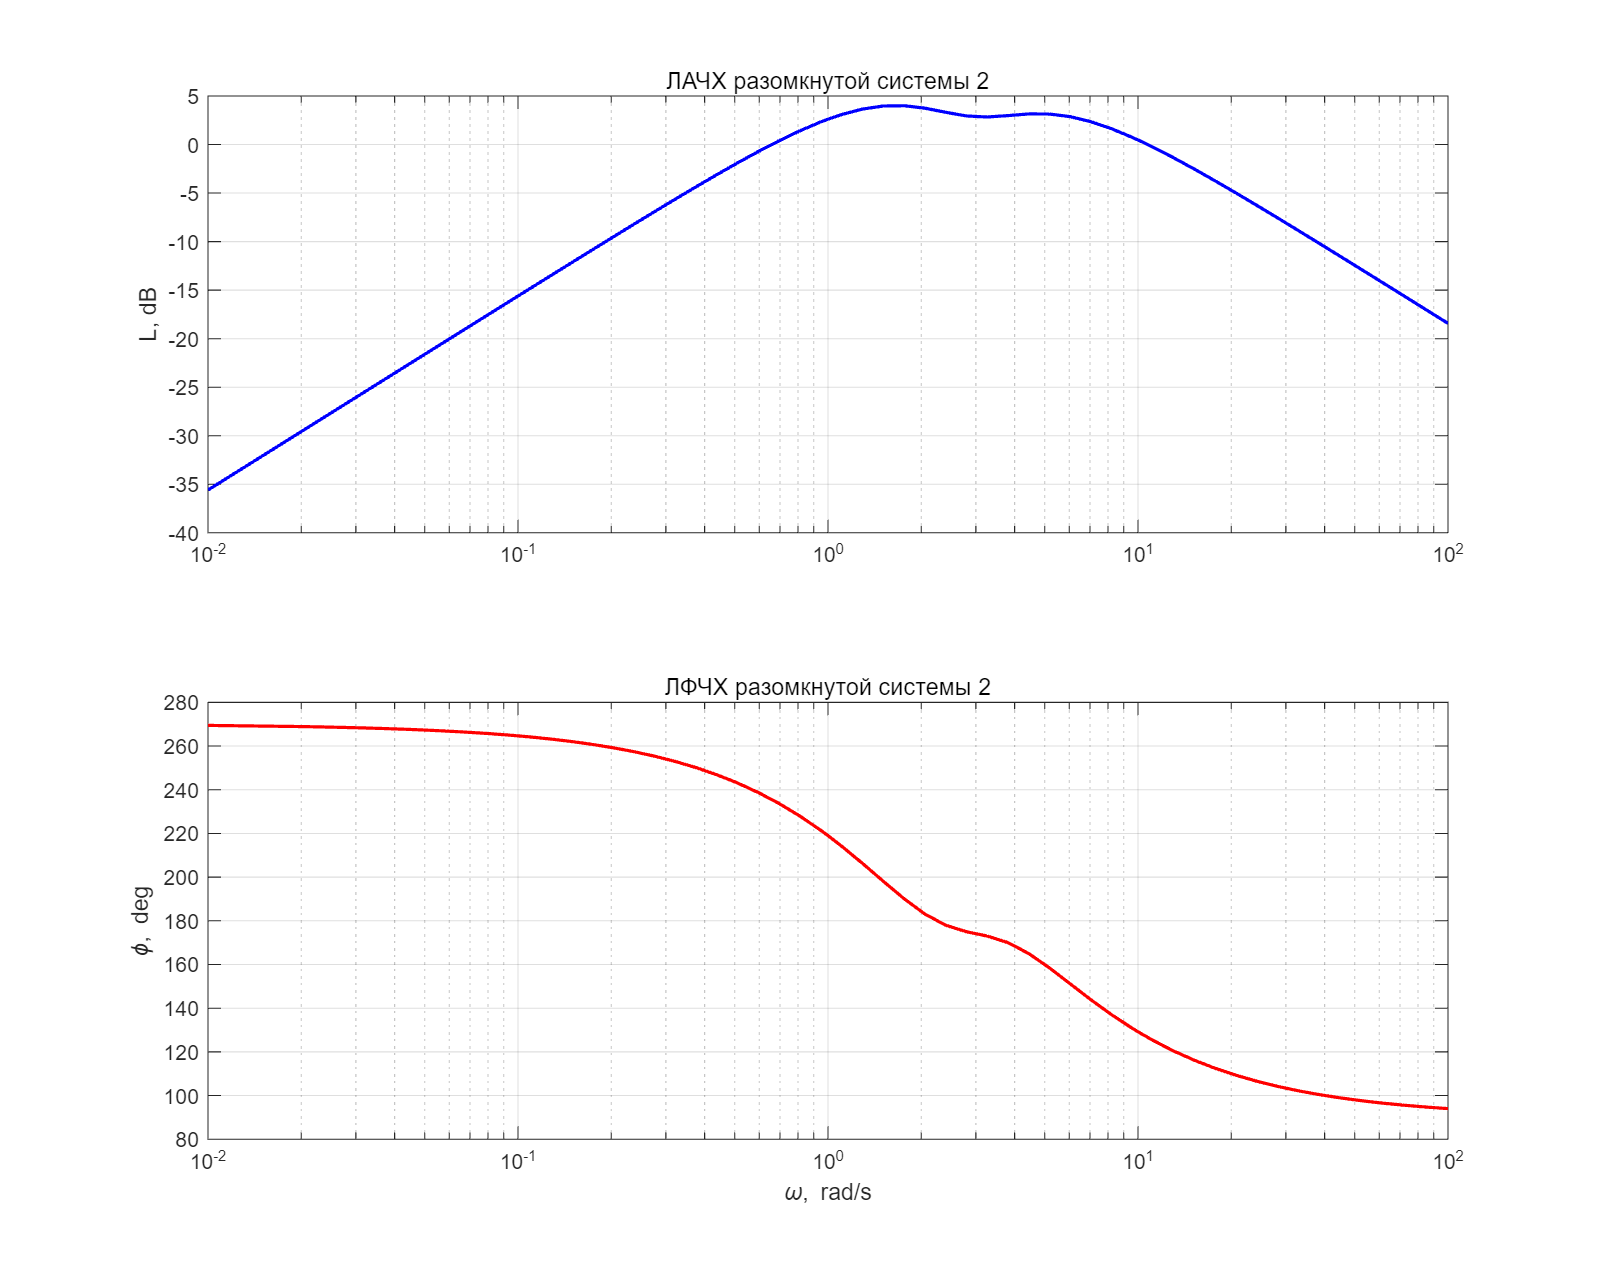


figure('Position', [100 100 1000 800]);
set(gcf, 'Color', 'w');

[mag2, phase2, w2] = bode(open_sys2);
mag2 = squeeze(mag2);
phase2 = squeeze(phase2);

subplot(2,1,1);
semilogx(w2, 20*log10(mag2), 'b', 'LineWidth', 1.5);
grid on;
ylabel('L, dB');
title('ЛАЧХ разомкнутой системы 2', 'FontWeight', 'normal');

subplot(2,1,2);
semilogx(w2, phase2, 'r', 'LineWidth', 1.5);
grid on;
xlabel('\omega, rad/s');
ylabel('\phi, deg');
title('ЛФЧХ разомкнутой системы 2', 'FontWeight', 'normal');

exportgraphics(gcf, "images/bode2.png", Resolution=200);

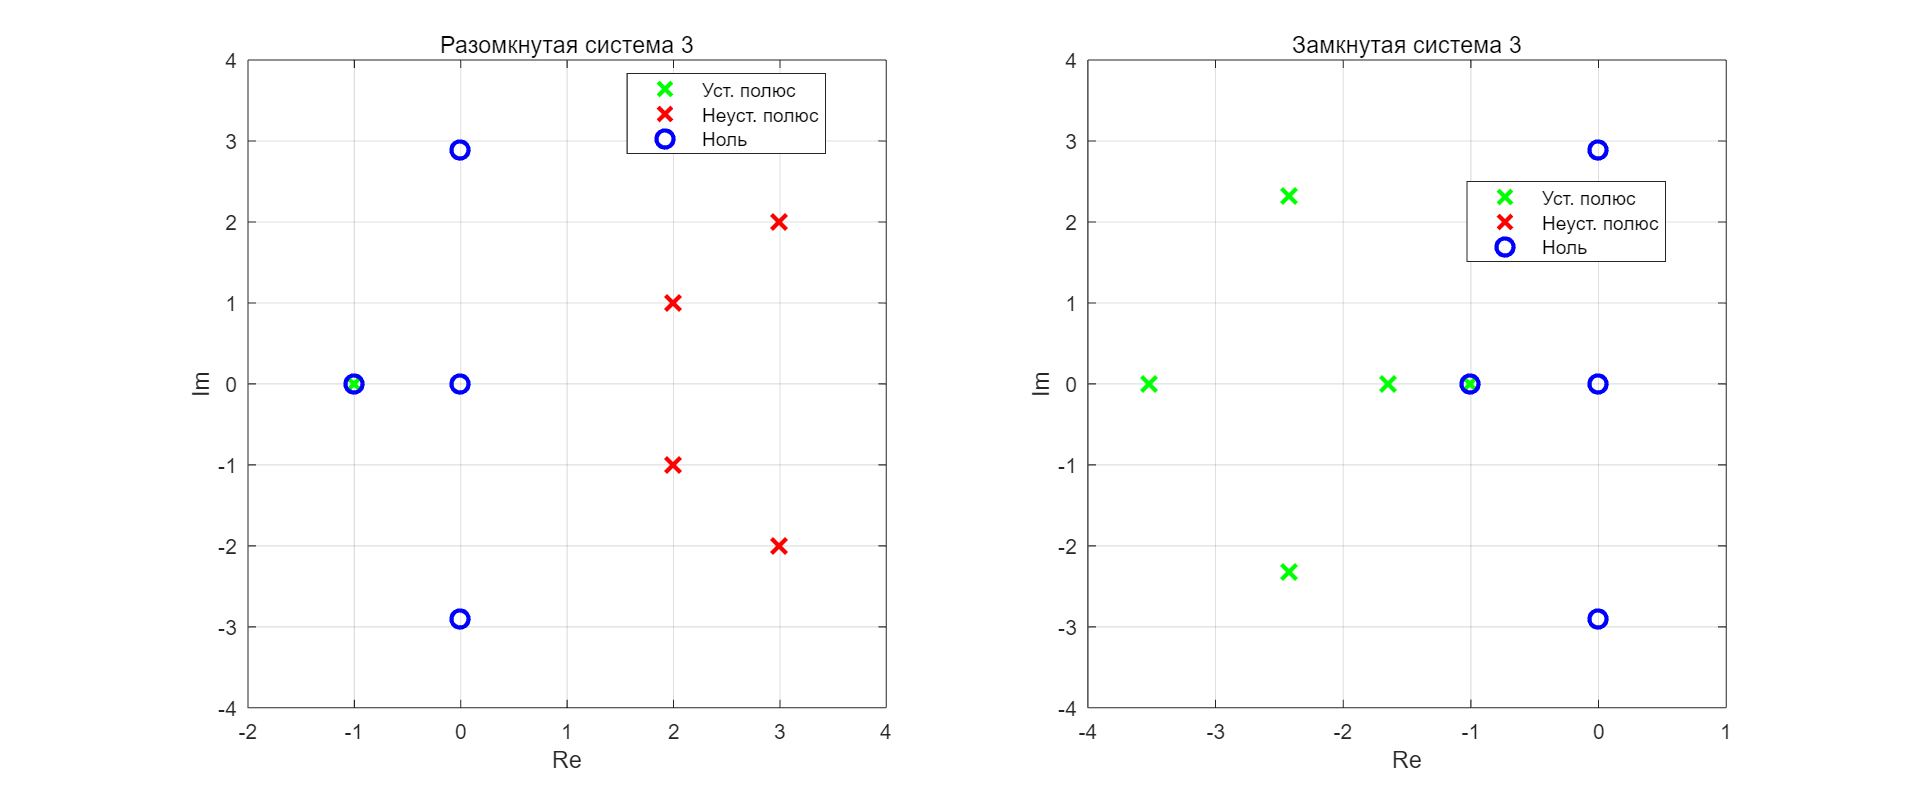

% Система 3
p3 = [-1, 2+1i, 2-1i, 3+2i, 3-2i];
z3 = roots([20, 20, 168, 168, 0]);
K3 = 20;
Q_closed_coeffs3 = [1, 11, 52, 128, 151, 65];
num3 = K3 * poly(z3);
den3 = poly(p3);
open_sys3 = tf(num3, den3);
R_s3 = Q_closed_coeffs3 - den3;
closed_sys3 = tf(R_s3, den3 + R_s3); 
p_closed3 = roots(den3 + R_s3);
z_closed3 = roots(R_s3);


figure('Position', [100 100 1200 500]);
set(gcf, 'Color', 'w');

subplot(1,2,1);
hold on;
grid on;
xlabel('Re');
ylabel('Im');
title('Разомкнутая система 3', 'FontWeight', 'normal');

for i = 1:length(p3)
    if real(p3(i)) < 0
        plot(real(p3(i)), imag(p3(i)), 'xg', 'MarkerSize', 10, 'LineWidth', 2);
    else
        plot(real(p3(i)), imag(p3(i)), 'xr', 'MarkerSize', 10, 'LineWidth', 2);
    end
end
for i = 1:length(z3)
    plot(real(z3(i)), imag(z3(i)), 'bo', 'MarkerSize', 8, 'LineWidth', 2);
end
xlim([-2 4]);
ylim([-4 4]);
box on;
h1 = plot(NaN, NaN, 'xg', 'MarkerSize', 10, 'LineWidth', 2);
h2 = plot(NaN, NaN, 'xr', 'MarkerSize', 10, 'LineWidth', 2);
h3 = plot(NaN, NaN, 'bo', 'MarkerSize', 8, 'LineWidth', 2);
legend([h1, h2, h3], {'Уст. полюс', 'Неуст. полюс', 'Ноль'}, 'Location', 'best');

subplot(1,2,2);
hold on;
grid on;
xlabel('Re');
ylabel('Im');
title('Замкнутая система 3', 'FontWeight', 'normal');

p_closed3 = pole(closed_sys3);
z_closed3 = zero(closed_sys3);
for i = 1:length(p_closed3)
    if real(p_closed3(i)) < 0
        plot(real(p_closed3(i)), imag(p_closed3(i)), 'xg', 'MarkerSize', 10, 'LineWidth', 2);
    else
        plot(real(p_closed3(i)), imag(p_closed3(i)), 'xr', 'MarkerSize', 10, 'LineWidth', 2);
    end
end
for i = 1:length(z_closed3)
    plot(real(z_closed3(i)), imag(z_closed3(i)), 'bo', 'MarkerSize', 8, 'LineWidth', 2);
end
xlim([-4 1]);
ylim([-4 4]);
box on;
h1 = plot(NaN, NaN, 'xg', 'MarkerSize', 10, 'LineWidth', 2);
h2 = plot(NaN, NaN, 'xr', 'MarkerSize', 10, 'LineWidth', 2);
h3 = plot(NaN, NaN, 'bo', 'MarkerSize', 8, 'LineWidth', 2);
legend([h1, h2, h3], {'Уст. полюс', 'Неуст. полюс', 'Ноль'}, 'Location', 'best');

exportgraphics(gcf, "images/pz_combined3.png", Resolution=200);

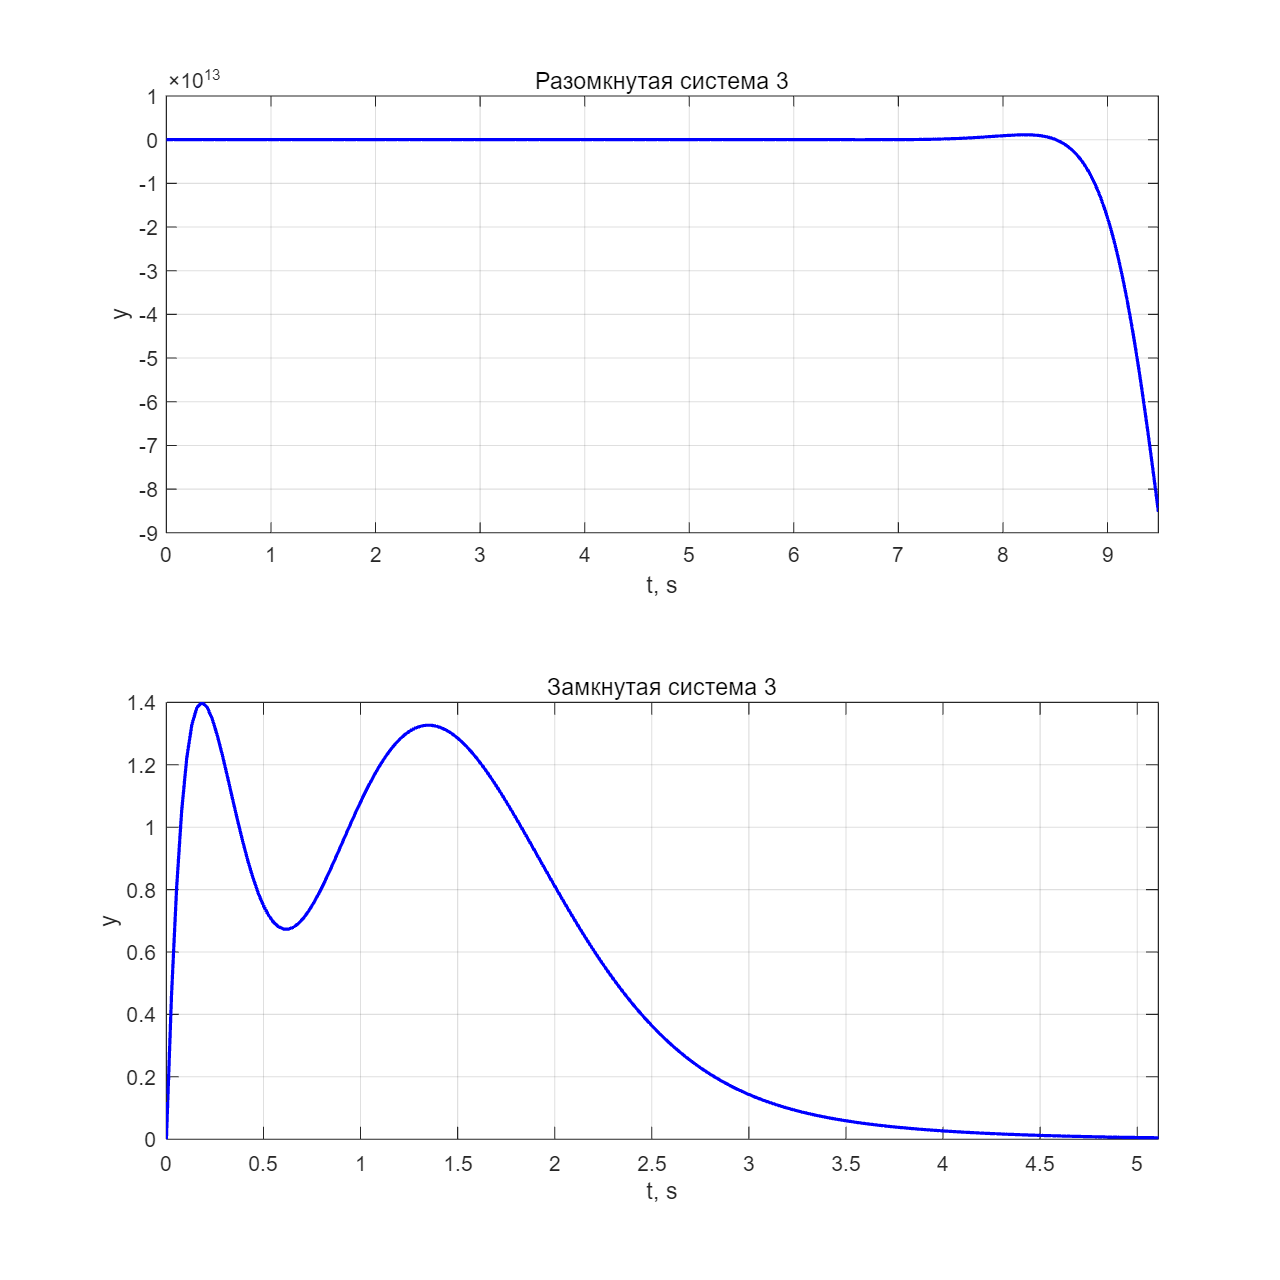


figure('Position', [100 100 800 800]);
set(gcf, 'Color', 'w');

subplot(2,1,1);
[y_open3, t3] = step(open_sys3);
plot(t3, y_open3, 'b', 'LineWidth', 1.5);
xlabel('t, s');
ylabel('y');
grid on;
title('Разомкнутая система 3', 'FontWeight', 'normal');
xlim([0 max(t3)]);

subplot(2,1,2);
[y_closed3, t_closed3] = step(closed_sys3);
plot(t_closed3, y_closed3, 'b', 'LineWidth', 1.5);
xlabel('t, s');
ylabel('y');
grid on;
title('Замкнутая система 3', 'FontWeight', 'normal');
xlim([0 max(t_closed3)]);

exportgraphics(gcf, "images/step_combined3.png", Resolution=200);

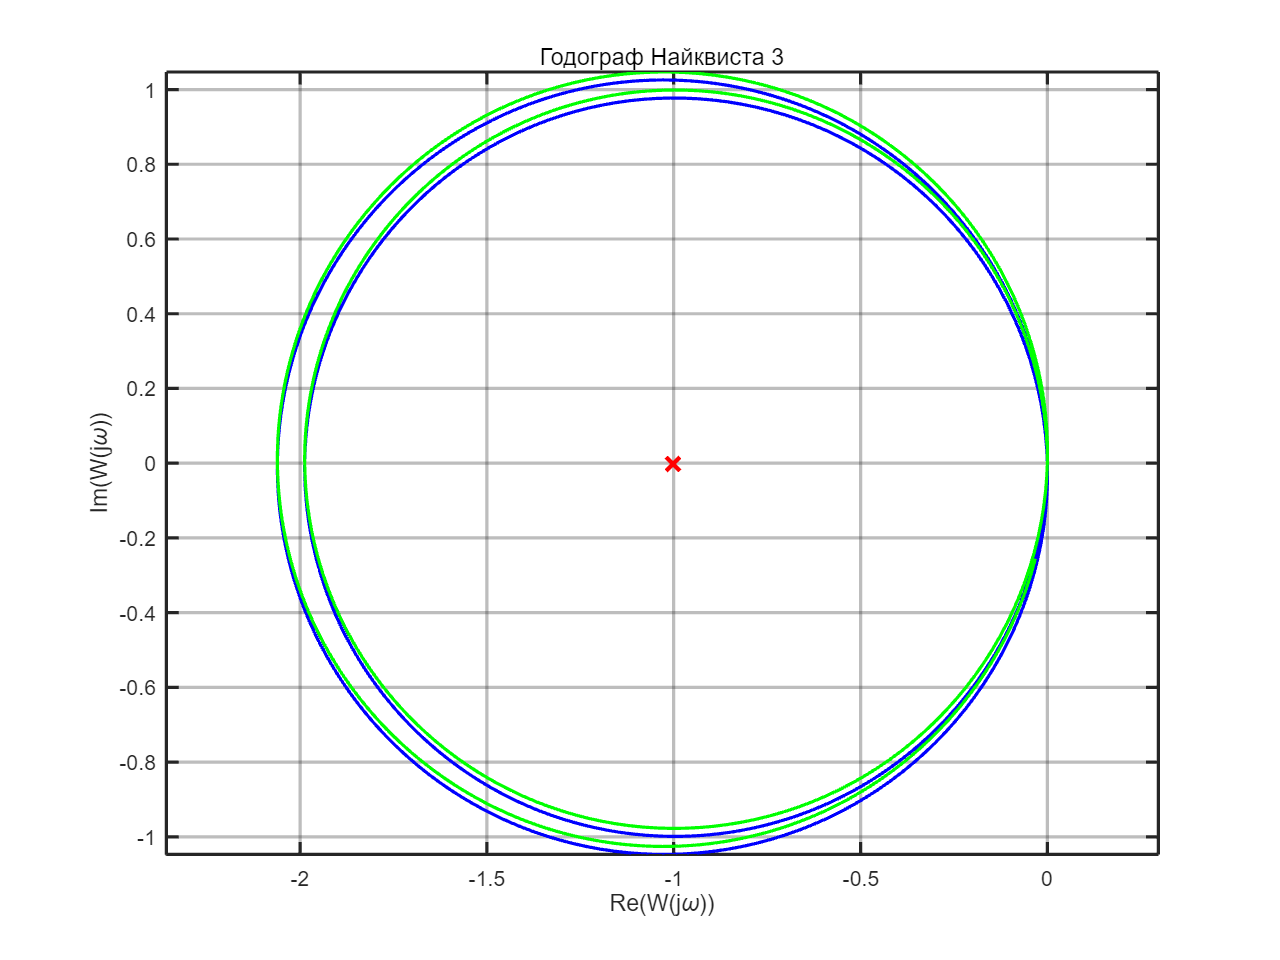


figure('Position', [100 100 800 600]);
set(gcf, 'Color', 'w');

[re3, im3] = nyquist(open_sys3, w);
re3 = squeeze(re3);
im3 = squeeze(im3);

plot(re3, im3, 'b', 'LineWidth', 1.5);
hold on;
plot(re3, -im3, 'g', 'LineWidth', 1.5, 'LineStyle', '-');
plot(-1, 0, 'xr', 'MarkerSize', 9, 'LineWidth', 2);
xlabel('Re(W(j\omega))');
ylabel('Im(W(j\omega))');
grid on;
title('Годограф Найквиста 3', 'FontWeight', 'normal');
axis equal;
box on;
ax = gca;
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.GridLineStyle = '-';
ax.GridAlpha = 0.3;
ax.LineWidth = 1.5;

exportgraphics(gcf, "images/nyquist3.png", Resolution=200);

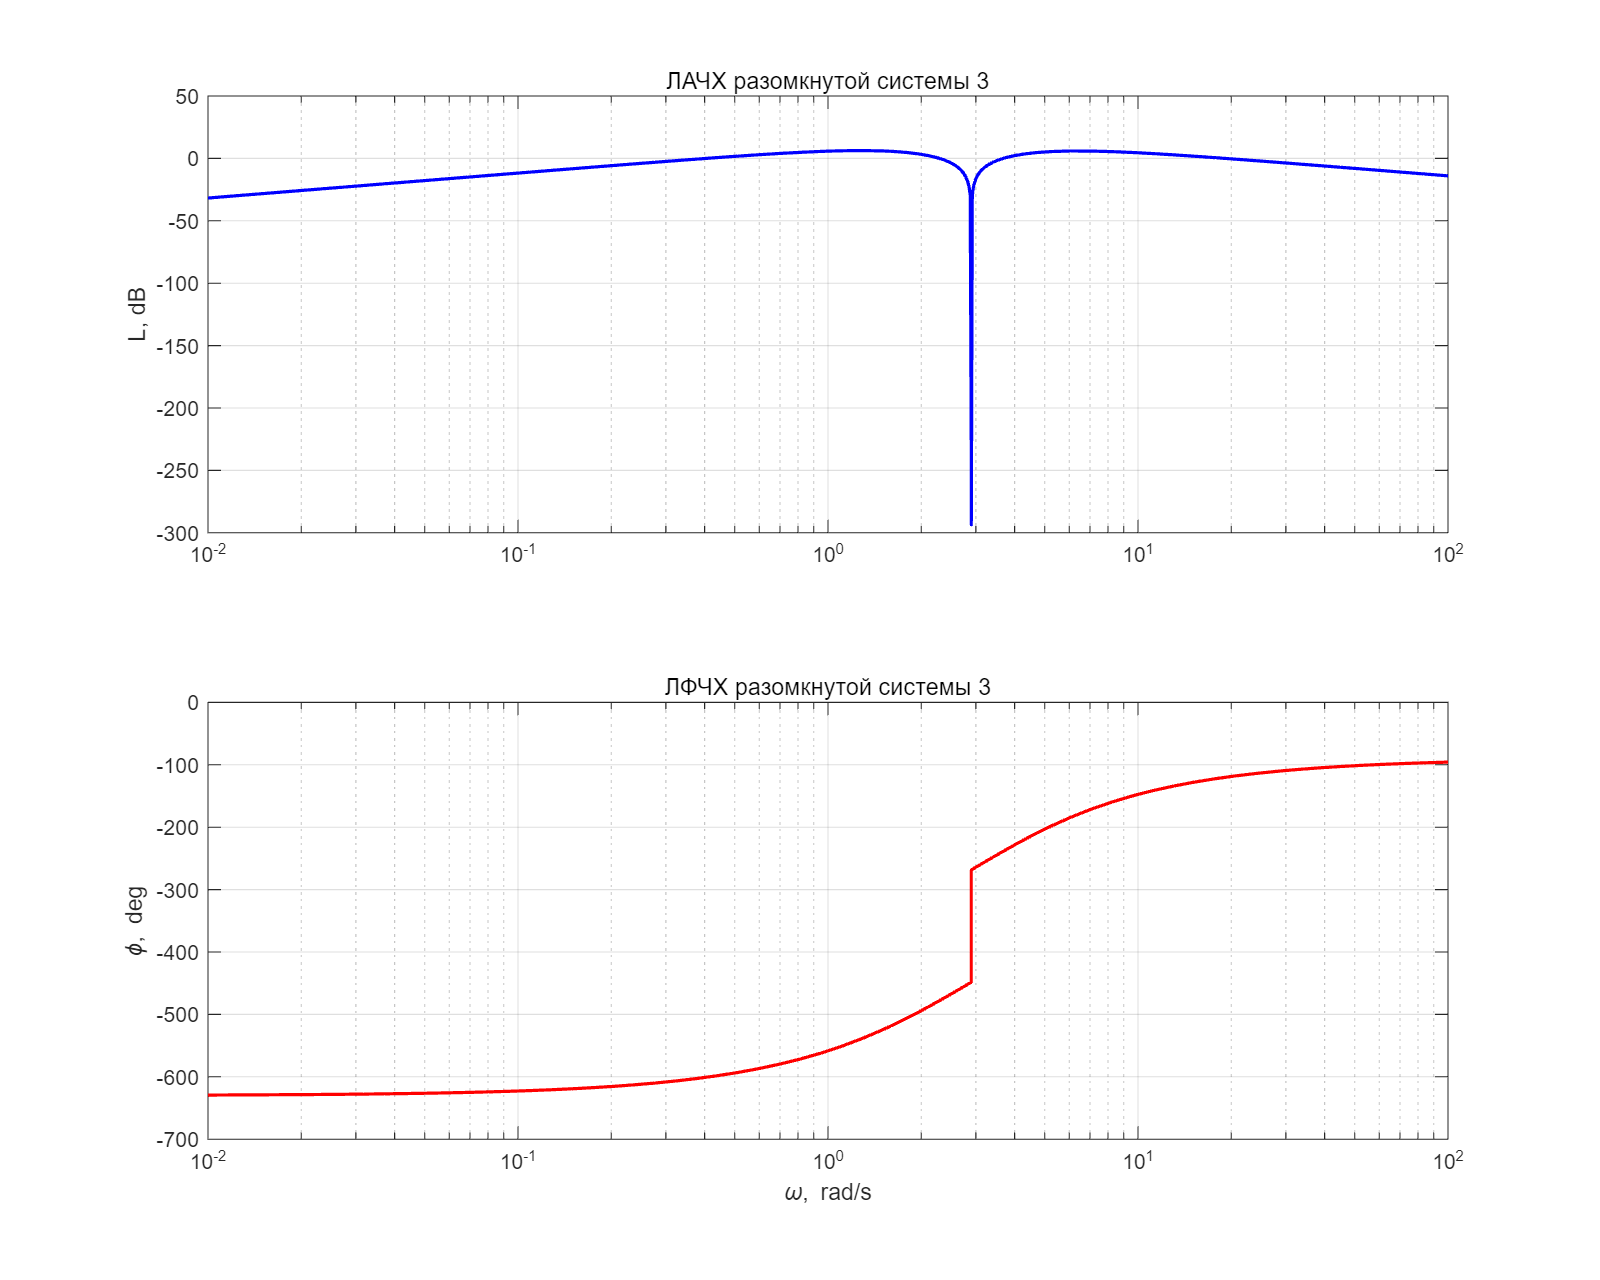


figure('Position', [100 100 1000 800]);
set(gcf, 'Color', 'w');

[mag3, phase3, w3] = bode(open_sys3);
mag3 = squeeze(mag3);
phase3 = squeeze(phase3);

subplot(2,1,1);
semilogx(w3, 20*log10(mag3), 'b', 'LineWidth', 1.5);
grid on;
ylabel('L, dB');
title('ЛАЧХ разомкнутой системы 3', 'FontWeight', 'normal');

subplot(2,1,2);
semilogx(w3, phase3, 'r', 'LineWidth', 1.5);
grid on;
xlabel('\omega, rad/s');
ylabel('\phi, deg');
title('ЛФЧХ разомкнутой системы 3', 'FontWeight', 'normal');

exportgraphics(gcf, "images/bode3.png", Resolution=200);